# Final project

Dmitry Shadrin, Eugenii Israelit @Skoltech

**Part 2. Tracking and forecasting in conditions of measurement gaps**

The trajectory of a moving object is disturbed by normally distributed unbiased random acceleration $a_i$ with variance $σ_a^2=〖0.2〗^2$ . 

In general, measurements of coordinate are performed every second with variance $σ_η^2=〖20〗^2$ of measurement noise.

Observation interval is 200 seconds.  However, there are measurement gaps. Probability of measurement gaps $P=0.3$

*Task**1:* Develop Kalman filter to track moving object under this conditions.

*Task**2:* Determine filtered and extrapolated errors of estimation (1 step and 7 steps ahead) over 500 runs of filter. Compare them with true estimation errors.

*Task 3. *Analyze the decrease of estimation accuracy in conditions of measurement gaps. Compare results when measurements are obtained without gaps.  

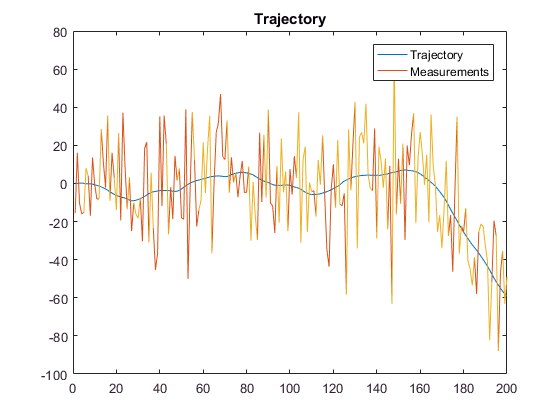

clc; clear; close all;
addpath('functions/');

n = 200;

x1 = 0;
v1 = 0;
t = 1; 

sigmaA = 0.2;
Acc = normrnd(0, sigmaA, 1, n);
sigmaN = 20;
Noise = normrnd(0,sigmaN,1, n);

X = calcTrajectory11( Acc, x1, v1, t);
M = X + Noise;

probability = 0.3;
Z = M;
Z( rand(1,n) < probability) = NaN;

plot(1:n, X, 1:n, M, 1:n, Z);
    title('Trajectory')
    legend('Trajectory', 'Measurements');

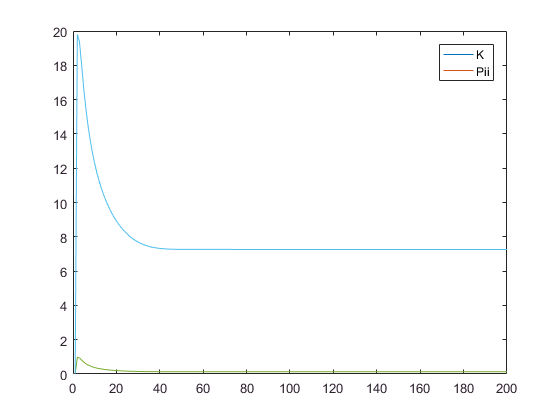

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];
Q = sigmaA^2 * (G*G');
P = [10000, 0; 0, 10000];

Xk = zeros(2, n);
Xk(:, 1) = [x1; v1];

for i=2:n
    P = F*P*F'+Q;
    K = P*H'/(H*P*H' + sigmaN^2);
    Xk(:,i) = F*Xk(:, i-1);
    Xk(:,i) = Xk(:,i) + K*(Z(i)-H*Xk(:,i));
    
    P = (eye(2)-K*H)*P;
    Kplot(:,i) = K;
    Pplot(i) = sqrt(P(1,1));
end
 
plot(Kplot(1,:));
hold on;
plot(Pplot);
legend('K','Pii')